# Cell Characterization for Battery Electric Vehicles

This example uses the test method defined in [1] to characterize a battery cell for electric vehicle applications. First you generate a high pulse power characterization (HPPC) by using Simscape™ Battery™ blocks and an in-built function to derive the battery cell parameters. Then you compare the model to the original battery model under typical drive-profile loading conditions.

## Battery HPPC Test Data 

A typical HPPC data is a set of discharge-charge pulses, applied to a battery at different state of charge (SOC) and at a given temperature. The magnitude of the pulse depends upon the cell capacity and the test temperature. At the end of every sequence of discharge-charge pulse operations, the SOC decreases by about 10% by applying a constant discharge current of C/3. A long rest time of one hour is recommended for the cells to relax after every sequence of discharge-charge pulses. This process continues until it covers all points of interest in the SOC range. For more information, see [1].

## Battery Parameter Estimation

The Battery (Table-Based) block in Simscape Battery uses the equivalent circuit modeling approach. You can capture different physical phenomena of a cell by connecting multiple resistor-capacitor (RC) pairs in series. In the Battery (Table-Based) block, you can select up to five RC pairs. You can derive the value of the resistance and time constant parameters from the HPPC test data.

This equation defines the voltage response of a battery cell:


$$V=V_0 -I\times R_o -I\times \left(\sum R_i \left(1-\exp \left(-\frac{t}{\tau_i }\right)\right)\right),$$


where:

- $V_0$ is the cell open-circuit potential.

- $R_o$ is the cell ohmic resistance.

- $R_i \;\textrm{and}\;\tau_i$ are the cell *i*-th RC pair resistance and time constant values.

- $I$ is the current passing through the cell.

- *t* is the elasped time.

All parameters are a function of the SOC and cell temperature. Since HPPC tests are typically performed at constant temperatures,  you can ignore the temperature dependence in the parameter estimation. This figure shows a typical discharge-charge profile. 

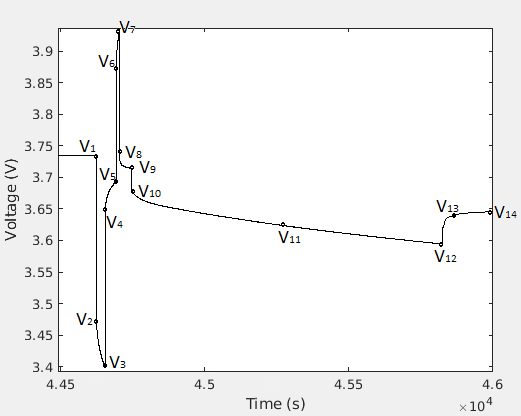

You can estimate the ohmic resistance $R_o$ from the sudden voltage change at the start of a discharge or a charge pulse (for example V1 to V2 or V5 to V6). To estimate the $R_i \;\textrm{and}\;\tau_i$ parameters, you can use the short voltage relaxation immediately after the discharge (V4 - V5) or the charge (V8 - V9) pulse. You can extract more time constants from the longer voltage relaxation (V12 - V14) after the SOC sweep step (V9 - V12). The `fminsearch` MATLAB function or the curvefit functions from the Curve Fitting Toolbox™ use the test data points to fit $R_i \;\textrm{and}\;\tau_i$ parameters at different SOC points. To find the open-circuit potential at a given SOC, use the period at the end of the long relaxation (V1) and just before the discharge-charge pulse operation.

In this example, you will use the `batteryData` function to estimate $V_0$, $R_o$ and $R_i -\;\tau_i$ parameters for the battery.

### Parameter Estimation Method

The `batteryData` function takes these arguments as input:

- HPPC data, specified as a column vector of time (in seconds), current (in Ampere), voltage (in Volt), and SOC (0-1). The 4th column in the HPPC data, SOC, is optional. You must ensure that the data covers the entire SOC range for the battery, starting from a fully charged cell (SOC=1) to a nearly depleted battery cell, to avoid any extrapolation of the parameters.

- Cell capacity and the initial SOC in the HPPC data, specified as an array of the two scalar values. This example uses the **cellProp** parameter to stores these values.

- The discharge pulse current (in A), the charge pulse current (in A), the SOC sweep current (in A), and the tolerance value to detect these current specified as an array of four scalar values. You must define tolerance to a suitable value (typically 0.01-0.05) for the function to detect current inflexion points in the HPPC data. This example uses the **hppcProtocol** parameter to stores these values

- Number of RC pairs specified as integer, along with their initial estimates specified as an array of scalar values, for the short (V4-V5 and V8-V9) and the long relaxation (V12-V14) curves.

- Data fit method, specified as `fminsearch` or `curvefit`.

- Option to enable debugging, specified as `true` or `false`. If `true`, the function plots the HPPC curve used for curve fit and the points selected for evaluating the ohmic resistance, dynamic parameters, and the open-circuit potential.

This code shows how to use the `batteryparametersLUT` function. Extracting the parameters is a two steps process:

You must provide the `exportResultsForLib` function these input arguments:

- The output of the `batteryData` function.

- A SOC range, specified as an array of SOC breakpoints. This example uses SOC breakpoints of 0:0.001:1.

- The plot option, specified as `true` or `false`. If `true`, the function plots all the estimated battery parameters as a function of the SOC range.

The `cellParameters` workspace variable stores the final parameterization data.

## Generate Synthetic Test Data

Run the `CellCharacterizationHPPC` SLX file to generate the current and voltage data for the selected cell. 

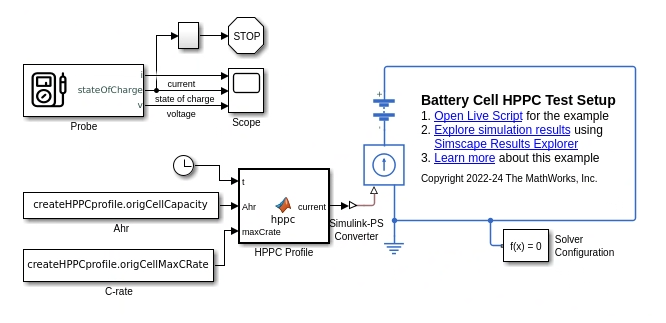

The HPPC Profile MATLAB function defines the discharge-charge protocols and the test method.

createHPPCprofile = load('origCellDataHPPCdataGen.mat');
hppcSim = sim('CellCharacterizationHPPC.slx');

The `hppcSim` workspace variable contains the current and voltage data for the HPPC profile used for battery cell parameter estimation.

## Fit Parameters to Test Data

Load the HPPC data and plot the voltage and current values. 

hppcTest = hppcSim.batteryHPPC_profile.extractTimetable;
testDataHPPC = [seconds(hppcTest.Time), hppcTest.current, hppcTest.voltage];

figure('Name','HPPC data - current pulses')
plot(testDataHPPC(:,1), testDataHPPC(:,2));

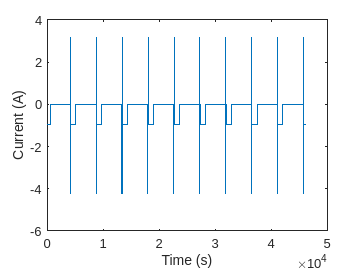

xlabel('Time (s)');ylabel('Current (A)')

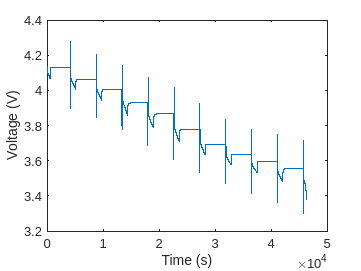

figure('Name','HPPC data - voltage response')
plot(testDataHPPC(:,1), testDataHPPC(:,3));
xlabel('Time (s)');ylabel('Voltage (V)')

Define the cell capacity (Ahr) as during the HPPC tests and the initial SOC (0-1).

cellInitialSOC = 1;
origCellCapacity = createHPPCprofile.origCellCapacity;

Define the pulse current magnitudes, in Amperes, as per the HPPC protocol.

testDataHPPCprotocol = [...
    createHPPCprofile.origCellCapacity*createHPPCprofile.origCellMaxCRate;...      % Max. discharge current
    0.75*createHPPCprofile.origCellCapacity*createHPPCprofile.origCellMaxCRate;... % Max. charge current
    createHPPCprofile.origCellCapacity/3;...                                       % SOC sweep current
    0.05];                                                                         % Tolerance value

The `batteryData` function detects a pulse (sudden change in current) based on the value you specify for the `testDataHPPCprotocol(1,1)` variable. If the function detects a sudden change in discharge current, it compares this discharge current to the value of the `testDataHPPCprotocol(1,1)` variable. If their difference, the tolerance, is within the value of the `testDataHPPCprotocol(4,1)` variable, the function identifies the pulse. This process also applies to the detection of the charge pulse (`testDataHPPCprotocol(2,1)`) and the SOC sweep (`testDataHPPCprotocol(3,1)`).

Define the number of RC pairs to consider and the initial estimates for the resistance and the time constant values. Specify the initial estimates for data extraction from short voltage relaxation (see section Battery Parameter Estimation).

cellDynamics.numPairShort     = 1;
cellDynamics.iniEstimateShort = [1e-3 10]; % [R1, Tau1, R2, Tau2 ....]

Specify the initial estimates for data extraction from long voltage relaxation (see section Battery Parameter Estimation). 

cellDynamics.numPairLong      = 3;
cellDynamics.iniEstimateLong  = [5e-4 0.1 1e-3 6 2e-3 60]; % [R1, Tau1, R2, Tau2 ....]

Identify pulse location and number in the HPPC data.

cellParams = CellCharacterizationMethod.batteryData ...
    (testDataHPPC, [createHPPCprofile.origCellCapacity; cellInitialSOC], ...
     testDataHPPCprotocol, ...
     cellDynamics.numPairShort, cellDynamics.iniEstimateShort,...
     cellDynamics.numPairLong, cellDynamics.iniEstimateLong,...
     "fminsearch", false);

*** Number of discharge pulses =10
*** Number of charge pulses    =10
*** Number of SOC sweep pulses =9


Estimate the resistance, time constant, and open circuit potential values at the state of charge points defined in the HPPC data.

cellParamData = extractParameters(cellParams, false);

To check if the function identified the correct pulses, at a MATLAB Command Window, enter:

Interpolate over a uniform state of charge range, the parameters to specify the battery dynamics in Simscape Battery (Table-Based) library block.

cellParameters = exportResultsForLib(cellParamData, 0:0.001:1, false);

In this example, we use the RC parameters fitted over long relaxation period (see section Battery Parameter Estimation) for the verification stage.

if CellCharacterizationMethod.checkFinalBatteryParameters(cellParameters, "long", cellDynamics.numPairShort, cellDynamics.numPairLong)
    error('There are negative numbers in the final parameterized results. You must change number of RC pairs or the initial estimates for the RC pairs.');
else
    save battCellCharacterizationResult.mat cellParameters origCellCapacity;
end

## Verify Parameters with Drive Profiles

A large battery pack for electric vehicle (BEV) uses the battery cell that you just parameterized. The `CellCharacterizationVerify.slx` model uses a drive profile to compare the parameterized cell against the original cell.

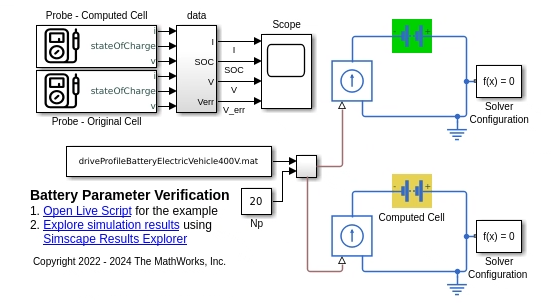

A typical load profile for a large battery pack (BEV) is:

driveProfile   = load('driveProfileBatteryElectricVehicle400V.mat');
driveProfileData.maxCurrentPack = max(driveProfile.ans.Data);
driveProfileData.minCurrentPack = min(driveProfile.ans.Data);

A single cell is not sufficient to power the BEV. Each cell must also be managed well electrically; the maximum C rate per cell musst not exceed the value specified by the supplier, or the value at which the cell has been tested (eg: HPPC). Parameter `origCellMaxCRate` specifies the maximum C rate a cell could be subjected to. In a drive profile, the current demand may exceed the current value specified by the maximum C rate and hence multiple cells need to be connected in parallel. 

Calculate the number of parallel cells required for the BEV application.

driveProfileData.currToCalcNp   = max(abs(driveProfileData.maxCurrentPack),abs(driveProfileData.minCurrentPack));
driveProfileData.verifyModelNp  = round(driveProfileData.currToCalcNp/(createHPPCprofile.origCellCapacity*createHPPCprofile.origCellMaxCRate),0);

Plot the drive profile data.

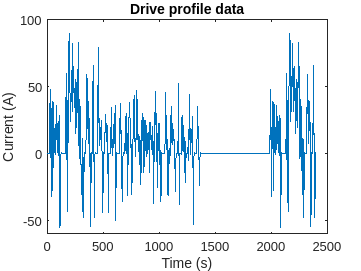

figure('Name','Drive profile');
plot(driveProfile.ans.Time,driveProfile.ans.Data)
title('Drive profile data')
xlabel('Time (s)');
ylabel('Current (A)');

The Computed Cell block in the `CellCharacterizationVerify` SLX file simulates the parameterized cell. The number of RC pairs you use in this script must be equal to the value you specified for the Charge Dynamics in the Computed Cell block. Run the `CellCharacterizationVerify` SLX file to compare the original and the parameterized cells.

createHPPCprofile = load('origCellDataHPPCdataGen.mat');
parameterizedCell = load('battCellCharacterizationResult.mat');

driveProfileData.mdl_verify = 'CellCharacterizationVerify'; 
load_system(driveProfileData.mdl_verify);
set_param([driveProfileData.mdl_verify,'/Np'],'Value',num2str(driveProfileData.verifyModelNp));
verifyRes = sim(driveProfileData.mdl_verify); 
bdclose(driveProfileData.mdl_verify);
resDriveProfile = verifyRes.CellCharacterization_DriveProfile.extractTimetable;

Plot the error between original cell used to create HPPC data and the parameterized cell.

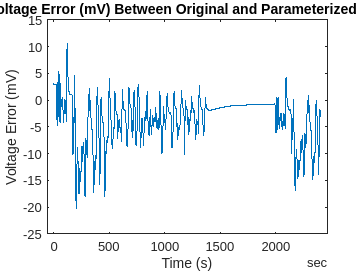

figure('Name','Error in voltage prediction');
plot(resDriveProfile.Time,resDriveProfile.V_err*1000);
title('Voltage Error (mV) Between Original and Parameterized Cell')
xlabel('Time (s)'); ylabel('Voltage Error (mV)');

Plot the voltage response of the original and the parameterized cell.

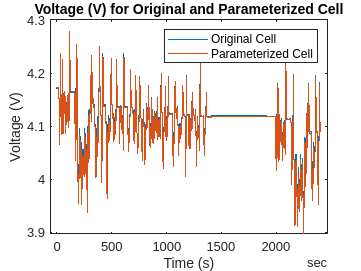

figure('Name','Voltage profile for original and parameterized cell');
plot(resDriveProfile.Time,resDriveProfile.V);
title('Voltage (V) for Original and Parameterized Cell')
xlabel('Time (s)'); ylabel('Voltage (V)'); legend('Original Cell', 'Parameterized Cell')

Display fitting accuracy results.

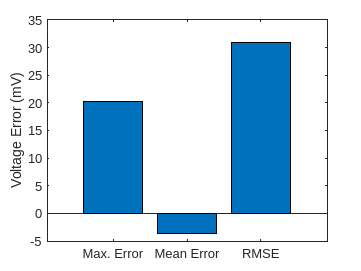

figure('Name','Voltage error plot between original and parameterized cell');
plotResult.maxVoltErr = round(max(abs(resDriveProfile.V_err*1000)),1);
plotResult.meanErr    = round(mean(resDriveProfile.V_err*1000),1);
plotResult.rmse       = round(sum((resDriveProfile.V_err*1000).^2)/length(resDriveProfile.V_err),1);
plotResult.labels     = {'Max. Error', 'Mean Error', 'RMSE'};
bar(plotResult.labels,[plotResult.maxVoltErr, plotResult.meanErr, plotResult.rmse]);
ylabel('Voltage Error (mV)');


disp(strcat("(1) ", num2str(plotResult.maxVoltErr),...
    " mV is the maximum voltage error between the original and the parameterized cell."));

(1) 20.3 mV is the maximum voltage error between the original and the parameterized cell.


disp(strcat("(2) ", num2str(plotResult.meanErr),...
    " mV is the mean voltage error between the original and the parameterized cell."));

(2) -3.6 mV is the mean voltage error between the original and the parameterized cell.


disp(strcat("(3) ", num2str(plotResult.rmse),...
    " mV is the rms-error between the original and the parameterized cell."));

(3) 30.9 mV is the rms-error between the original and the parameterized cell.


If the error is not within your acceptable limits, try with a different:

- Initial estimate, or 

- Different number of RC pairs, or 

- Using a different fitting method - fminsearch, curvefit

If you want to characterize the battery at multiple temperatures, use this workflow to fit the parameters at each individual temperature and then combine them inside the temperature dependent block.

## Reference

- Christophersen, Jon P. Battery Test Manual For Electric Vehicles, Revision 3. United States: N. p., 2015. Web. doi:10.2172/1186745

*Copyright 2022 - 2024 The MathWorks, Inc.*